clear all;
close all;

Draw stability region

Delta_t=0.2; 
 
relamdt=-4:0.1:4;
imlamdt=-4:0.1:4;
[RElamdt,IMlamdt]=meshgrid(relamdt,imlamdt);
axis square;
lamdt=RElamdt+i*IMlamdt;
sig=1+lamdt+lamdt.^2/2;  
%sig=1+lamdt+lamdt.^2/2+lamdt.^3/6+lamdt.^4/24;  
contour_levels=[1 1];
hold off
contour(RElamdt,IMlamdt,abs(sig),contour_levels,'linewidth',4);
hold on
sig=1+lamdt; 
contour(RElamdt,IMlamdt,abs(sig),contour_levels,'linewidth',4);
xlabel('Re \lambda \Delta t','Fontsize',14);
ylabel('Im \lambda \Delta t','Fontsize',14);
hold on;
plot([-4 4],[0 0],'k');
plot([0 0],[-4 4],'k');
title('contour |\sigma|','Fontsize',14);
eigenvalues=eig([-3 6 9;1 -9 2;2 -15 -9])

eigenvalues =   -2.3440 + 0.0000i
  -9.3280 + 3.2030i
  -9.3280 - 3.2030i


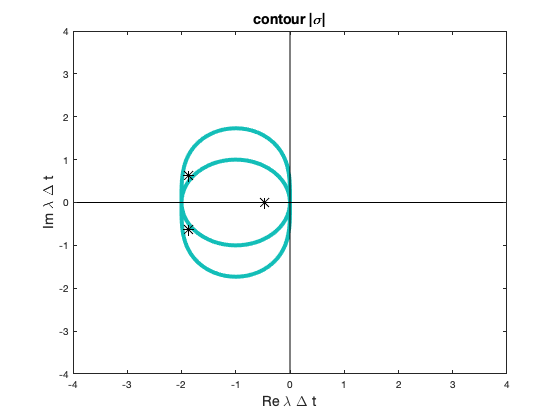

plot(real(Delta_t*eigenvalues),imag(Delta_t*eigenvalues),'k*',"MarkerSize",10)

RK-2, Euler Solutions and MATLAB ode23() solutions

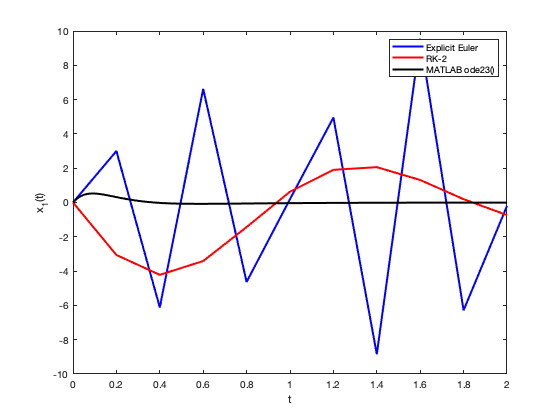

tmax=2.0;
%Delta_t=0.02;            
t=0:Delta_t:tmax;          
xRK2=zeros(length(t),3);
xEuler=zeros(length(t),3);
xRK2(1,:)=[0.0 1.0 1.0]; 
xEuler(1,:)=[0.0 1.0 1.0];
 
for n=1:length(t)-1
    k1=f(t(n),xRK2(n,:))';
    k2=f(t(n)+Delta_t,xRK2(n,:)+Delta_t*k1)';
    xRK2(n+1,:)=xRK2(n,:)+Delta_t*(k1/2.0+k2/2.0);
    
    xEuler(n+1,:)=xEuler(n,:)+Delta_t*f(t(n),xEuler(n,:))';
end
 
[tmat,xmat]=ode23(@f,[0 tmax],[0 1 1]);
 
figure
plot(t,xEuler(:,1),'b-','linewidth',2,'markersize',10)   
hold on
plot(t,xRK2(:,1),'r-','linewidth',2,'markersize',10) 
plot(tmat,xmat(:,1),'k-','linewidth',2)
xlabel('t');ylabel('x_1(t)');
legend('Explicit Euler','RK-2','MATLAB ode23()')

function dxdt=f(t,x)
dxdt=[-3*x(1)+6*x(2)+9*x(3); 1*x(1)-9*x(2)+2*x(3) ;2*x(1)-15*x(2)-9*x(3)];
end